# 11A주차 — 루프 성형 : 루프이득의 모양을 내가 정한다

**제어시스템설계** · 충남대학교 자율운항시스템공학과

9주차에서 보드 선도를 그렸고, 10주차에서 나이퀴스트로 안정성을 판정하고 이득여유와 위상여유를 읽었습니다. 그런데 거기까지는 전부 **읽기**였습니다. 남의 시스템을 보고 "이건 위상여유가 30도네" 하고 판정만 한 것입니다.

오늘부터는 **쓰기**입니다. 루프이득 $L(s)$ 의 모양을 내가 원하는 대로 만들어 놓고, 그 모양에서 성능이 자동으로 따라 나오게 하는 것입니다. 이것을 **루프 성형**(loop shaping) 이라고 합니다.

오늘 할 일은 설계가 아니라 **설계의 언어를 익히는 것**입니다.

선수 지식은 9주차(보드 선도)와 10주차(여유)입니다. 그 두 주차가 흐릿하면 오늘 2절과 3절이 복습을 겸하니 거기서 다시 잡으면 됩니다.

if isempty(which('plant_msd'))   % 경로가 아직 등록 안 되었으면 알아서 잡는다
    p_ = pwd;
    if ~isempty(mfilename('fullpath')), p_ = fileparts(mfilename('fullpath')); end
    for k_ = 1:4
        if isfile(fullfile(p_,'setup_path.m')), run(fullfile(p_,'setup_path.m')); break; end
        p_ = fileparts(p_);
    end
    clear p_ k_
end
clc; close all;
s = tf('s');

## 0-0. 오늘 돌려 볼 파일

강의노트를 읽다가 **직접 값을 바꿔 보고 싶을 때** 여는 파일들입니다. 모두 `W11A_LoopShaping` 폴더 안에 있습니다.

실행하는 법 — 파일을 열고 절 안에서 `Ctrl+Enter` 를 누르면 그 절만 돕니다. 전체는 `F5` 입니다. 처음 한 번은 `setup_path` 를 먼저 실행하십시오.

이 강의노트의 **그림은 전부** `make_figures.m` 이 만들어 `common/figures/` 에 넣어 둔 것입니다. 그림마다 어느 함수가 만들었는지 아래에 적어 두었습니다.

## 0. 오늘 한 장 요약

오늘 배우는 것을 한 문장으로 적으면 이렇습니다.

**좋은 제어기란 루프이득을 저주파에서 높이고 고주파에서 낮추며 그 사이를 완만하게 지나가게 만든 것이다.**

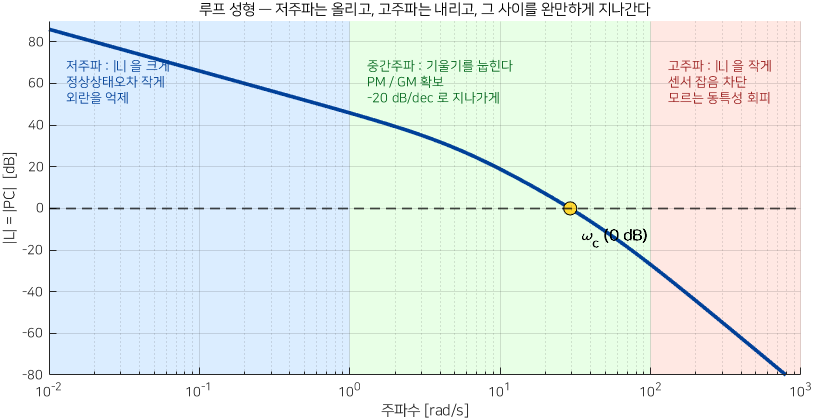

주파수축을 셋으로 나눠 요구사항을 배치한다

**그림 파일** `w11a_bands.png` — `make_figures.m` 의 `fig_w11a_bands` · 다시 만들려면 `make_figures('w11a_bands')`

**직접 확인해 보려면** — `W11A_01_L_S_T.m` 의 **3절**이 같은 그림을 모터 플랜트로 다시 그립니다.

그림 해석

이 그림 한 장에 오늘 배울 것이 다 들어 있습니다. 왼쪽을 올리고 오른쪽을 내리고 가운데를 눕히는 것, 그것이 루프 성형입니다. 그런데 **왼쪽을 올리면 오른쪽도 같이 올라가려 하고**, 가운데를 급하게 꺾으면 위상여유가 사라집니다. 그 맞바꿈이 오늘의 주제입니다.

오늘의 계단

- **1절** 루프이득 $L$ 과 두 식 $S$, $T$ — 그리고 $S+T=1$

- **2절** 모터 예제 — 손으로 전부 되는 루프 하나

- **3절** 네 숫자 : $\omega_c$, GM, PM, $\omega_b$ 와 서로의 관계

- **4절** 주파수 띠 세 개 — 요구사항을 나눠 싣는다

- **5절** 왜 되먹임인가 — 외란이 답한다

- **6절** 공짜가 아니다 — 센서 잡음이라는 대가

## 0-1. 가장 작은 예 — 샤워기를 얼마나 세게 돌리는가

1주차의 샤워기로 돌아갑니다. 물이 차면 손잡이를 온수 쪽으로 돌립니다. 여기서 **"얼마나 세게 돌리는가"** 가 바로 루프이득입니다.

- 조금만 돌린다 ($|L|$ 작다) — 온도가 천천히 맞는다. 누가 옆에서 물을 틀면 (외란) 그대로 당한다

- 많이 돌린다 ($|L|$ 크다) — 금방 맞는다. 외란도 금방 잡아낸다

- 너무 많이 돌린다 — 뜨겁다 차갑다를 왕복한다. **발산한다**

그런데 중요한 것이 하나 더 있습니다. **빠르게 변하는 것에는 세게 반응하면 안 된다**는 것입니다. 수도관이 잠깐 덜컥거린 것(잡음)에 손잡이를 확 돌리면 오히려 온도가 엉망이 됩니다.

즉 **"천천히 변하는 것에는 세게, 빨리 변하는 것에는 약하게"** 반응해야 합니다. 이것이 바로 저주파 이득은 크게, 고주파 이득은 작게 라는 말입니다. 오늘 배우는 모든 것이 이 한 문장의 수학적 표현입니다.

숫자가 하나뿐인 예로 확인합니다. 루프이득이 $L = 100/s$ 라고 해 봅시다. 적분기 하나뿐인 가장 단순한 루프입니다.

L0 = 100/s;
T0 = feedback(L0, 1);             % 폐루프 (지령 -> 출력)
S0 = 1 - T0;                      % 오차가 남는 비율
w0 = [0.1 1 10 100 1000]';
tbl0 = table(w0, ...
    20*log10(squeeze(abs(freqresp(L0, w0)))), ...
    20*log10(squeeze(abs(freqresp(S0, w0)))), ...
    20*log10(squeeze(abs(freqresp(T0, w0)))), ...
    'VariableNames', {'w_rad_s', 'L_dB', 'S_dB', 'T_dB'})

표를 읽는 법입니다.

- $\omega = 0.1$ 에서 $|L| = 60$ dB (1000 배) 입니다. 이때 $|S| = -60$ dB, 즉 오차가 $1/1000$ 로 줄어듭니다. **루프이득이 크면 오차가 작다**

- $\omega = 100$ 에서 $|L| = 0$ dB (딱 1배) 입니다. 여기가 교차주파수입니다

- $\omega = 1000$ 에서 $|L| = -20$ dB 입니다. $|T| \approx -20$ dB, 즉 이 빠른 지령은 $1/10$ 밖에 못 따라갑니다. **루프이득이 작으면 못 따라간다**

왜 중요한가 — 표의 세 열이 완전히 맞물려 움직입니다. $L$ 을 정하면 $S$ 와 $T$ 가 따라 정해집니다. 그러니 $L$** 의 모양만 설계하면 된다**는 것이 오늘의 전략입니다.

## 1. 루프이득 $L$ — 한 바퀴 돌아오는 길

왜 필요한가 — 위에서 $L$, $S$, $T$ 라는 기호를 썼습니다. 세 개가 각각 무엇인지, 어디서 나온 것인지 정확히 정의하고 넘어가야 합니다.

1주차와 10주차에서 쓴 블록선도를 다시 봅니다.

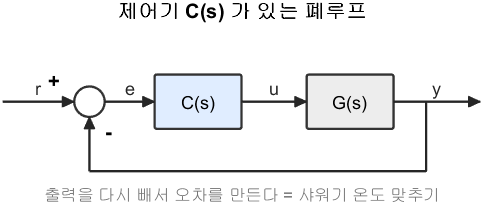

제어기가 있는 단위 되먹임 루프

**그림 파일** `loop_controller.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_controller')`

그림 해석

이 그림에서 신호를 따라가며 식을 세웁니다. 4-8-0 절의 네 단계 그대로입니다.


$$e = r - y, \qquad u = C e, \qquad y = P u$$


뒤에서부터 대입합니다.


$$y = P u = P C e = P C (r - y)$$


$y$ 가 양변에 있으므로 한쪽으로 모읍니다. $(1 + PC)$** 가 생기는 자리가 바로 여기입니다.**


$$y + P C y = P C r \quad \Longrightarrow \quad (1 + P C)\, y = P C\, r$$


나눕니다.


$$\frac{y}{r} = \frac{P C}{1 + P C}$$


여기서 분모에 반복해서 나오는 $PC$ 에 이름을 붙입니다. 이것이 **루프이득**입니다.


$$L(s) \;=\; P(s)\,C(s)$$


이름의 뜻 — 합산점에서 출발해 $C$ 와 $P$ 를 지나 되먹임 선을 타고 **제자리로 돌아올 때까지 신호에 곱해지는 양**입니다. 한 바퀴(loop) 도는 동안의 이득입니다.

10주차에서 나이퀴스트 선도를 그린 것도, 보드 선도에서 여유를 읽은 것도 전부 이 $L(j\omega)$ 였습니다. 같은 것에 이제 이름을 붙인 것입니다.

왜 중요한가 — 설계에서 내가 만지는 것은 $C$ 하나뿐인데, 성능은 전부 $L = PC$ 로 결정됩니다. 그래서 "$C$ 를 어떻게 할까" 가 아니라 **"**$L$** 을 어떤 모양으로 만들까"** 를 먼저 정하는 것이 순서가 맞습니다.

## 1-1. 두 개의 이름 — 감도함수 $S$ 와 상보감도함수 $T$

왜 필요한가 — $y/r$ 하나만으로는 설계를 못 합니다. 오차는 얼마나 남는지, 외란은 얼마나 들어오는지도 알아야 합니다. 그 답이 같은 블록선도에서 두 개 더 나옵니다.

**첫째, 오차는 얼마나 남는가.** 위의 유도에서 $e$ 를 구해 봅니다.


$$e = r - y = r - P C e \quad \Longrightarrow \quad (1 + PC)\, e = r$$



$$\frac{e}{r} = \frac{1}{1 + PC} = \frac{1}{1+L} \;\equiv\; S(s)$$


이것을 **감도함수**(sensitivity function) $S$ 라고 부릅니다.

**둘째, 출력은 얼마나 따라가는가.** 방금 유도한 것입니다.


$$\frac{y}{r} = \frac{PC}{1+PC} = \frac{L}{1+L} \;\equiv\; T(s)$$


이것을 **상보감도함수**(complementary sensitivity function) $T$ 라고 부릅니다. "상보" 는 $S$ 를 보완해서 1 을 만든다는 뜻입니다. 바로 다음 절에서 확인합니다.

기호를 정리해 둡니다. 오늘 내내 쓰는 네 개입니다.

$S$ 와 $T$ 는 둘 다 **무차원**입니다. 비율이기 때문입니다. 그래서 dB 로 그려서 0 dB 선과 비교하는 것이 의미가 있습니다. $|S| = -40$ dB 는 "오차가 1 % 로 줄었다" 는 뜻이고, $|T| = 0$ dB 는 "지령을 100 % 따라간다" 는 뜻입니다.

왜 "감도" 라는 이름인가 — 1주차 8절에서 모델오차에 대한 민감도를 구했을 때 똑같은 $\frac{1}{1+KG}$ 가 나왔습니다. 플랜트가 10 % 틀렸을 때 폐루프 성능이 몇 % 변하는가 — 그 비율이 $S$ 입니다. 외란이 들어오는 비율과 모델오차에 민감한 정도가 **같은 식**이라는 것이 되먹임 이론의 출발점입니다.

## 1-2. $S + T = 1$ — 오늘 가장 중요한 한 줄

왜 필요한가 — 설계자는 보통 이렇게 바랍니다. "오차도 작고($|S|$ 작고) 추종도 잘 되게($|T|$ 크게) 해 주세요." 그런데 그것은 **원하는 것이 아니라 자동으로 따라오는 것**입니다. 더 중요한 것은 **둘을 동시에 작게 만들 수 없다**는 사실입니다. 그 이유가 이 한 줄에 있습니다.

유도는 두 줄입니다. 분모가 같으니 그냥 더합니다.


$$S + T = \frac{1}{1+L} + \frac{L}{1+L} = \frac{1 + L}{1 + L} = 1$$


**모든 주파수에서, 어떤 **$P$** 와 **$C$** 에 대해서도** 성립합니다. 설계로 깰 수 없습니다. 분모가 같은 두 분수를 더한 것이니 당연한데, 결과는 전혀 당연하지 않습니다.

손으로 한 번 확인합니다. 위의 $L = 100/s$ 에 $\omega = 100$ 을 넣습니다.


$$L(j100) = \frac{100}{j100} = -j$$



$$S = \frac{1}{1-j} = \frac{1+j}{2}, \qquad T = \frac{-j}{1-j} = \frac{-j(1+j)}{2} = \frac{1-j}{2}$$



$$S + T = \frac{1+j}{2} + \frac{1-j}{2} = \frac{2}{2} = 1$$


허수부가 서로 지워지고 실수부만 남아 **정확히 1** 이 됩니다.

MATLAB 으로 네 주파수에서 검산합니다.

wchk = [0.1 1 10 100]';
Schk = squeeze(freqresp(S0, wchk));
Tchk = squeeze(freqresp(T0, wchk));
table(wchk, Schk, Tchk, Schk + Tchk, ...
    'VariableNames', {'w_rad_s', 'S', 'T', 'S_plus_T'})

마지막 열이 전부 정확히 $1 + 0i$ 입니다. 반올림 오차조차 없습니다.

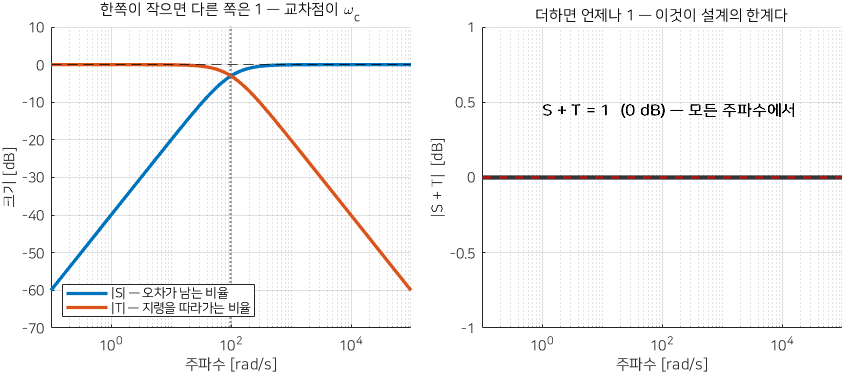

한쪽을 작게 하면 다른 쪽은 1 에 가까워진다

**그림 파일** `w11a_s_plus_t.png` — `make_figures.m` 의 `fig_w11a_s_plus_t` · 다시 만들려면 `make_figures('w11a_s_plus_t')`

**직접 확인해 보려면** — `W11A_01_L_S_T.m` 의 **2절**

그림 해석

이 제약을 어떻게 사는가 — **주파수마다 다른 것을 요구하면 됩니다.**

- 저주파에서는 $|S|$ 를 작게 (오차와 외란을 잡겠다). 그러면 $|T| \approx 1$ 이 되는데, 저주파 지령은 어차피 따라가고 싶은 것이니 **문제가 아니라 덕입니다**

- 고주파에서는 $|T|$ 를 작게 (잡음을 막겠다). 그러면 $|S| \approx 1$ 이 되는데, 고주파 지령은 어차피 따라갈 생각이 없으니 **괜찮습니다**

- 중간주파수에서는 둘 다 1 근처입니다. 여기는 포기하는 대신 **안정성**을 챕니다

왜 중요한가 — 4절의 "주파수 띠 세 개" 가 바로 이 결론입니다. 그리고 11B 주차에서 설계할 때, 사양을 모든 주파수에서 동시에 만족시키려 하지 않고 **띠별로 나눠 배정**하는 이유도 이것입니다.

## 1-3. $|L|$ 이 크면, 작으면 — 근사식 두 개

왜 필요한가 — $S$ 와 $T$ 를 매번 계산하기는 번거롭습니다. 그런데 극단적인 두 경우에는 암산으로 됩니다. 설계할 때 실제로 쓰는 것은 이 두 근사식입니다.

**첫째, **$|L| \gg 1$** (저주파) 일 때.** 분모의 1 을 무시합니다.


$$S = \frac{1}{1+L} \approx \frac{1}{L}, \qquad T = \frac{L}{1+L} \approx \frac{L}{L} = 1$$


dB 로 쓰면 더 쓰기 좋습니다. $|S|_{dB} \approx -|L|_{dB}$ 입니다. **보드 선도의 **$|L|$** 곡선을 0 dB 선 기준으로 뒤집으면 그게 **$|S|$** 입니다.**

**둘째, **$|L| \ll 1$** (고주파) 일 때.** 분모의 $L$ 을 무시합니다.


$$S = \frac{1}{1+L} \approx 1, \qquad T = \frac{L}{1+L} \approx L$$


dB 로 $|T|_{dB} \approx |L|_{dB}$ 입니다. **고주파에서는 **$|T|$** 가 **$|L|$** 과 그냥 같습니다.**

정리하면 이렇습니다. 이 표가 오늘의 핵심 도구입니다.

근사가 실제로 맞는지 수치로 확인합니다. $L = 100/s$ 에서 $\omega = 1$ (저주파, $|L| = 40$ dB) 과 $\omega = 10^4$ (고주파, $|L| = -40$ dB) 를 봅니다.

wlo = 1;  whi = 1e4;
LdB_lo = 20*log10(abs(freqresp(L0, wlo)));
LdB_hi = 20*log10(abs(freqresp(L0, whi)));
cmp = table( ...
    {'저주파 w=1'; '고주파 w=1e4'}, ...
    [LdB_lo; LdB_hi], ...
    [20*log10(abs(freqresp(S0, wlo))); 20*log10(abs(freqresp(T0, whi)))], ...
    [-LdB_lo; LdB_hi], ...
    'VariableNames', {'영역', 'L_dB', '실제_dB', '근사_dB'})

저주파에서 $|S|$ 는 $-40.0$ dB 이고 근사식 $-|L|_{dB}$ 도 $-40.0$ dB 입니다. 고주파에서 $|T|$ 는 $-40.0$ dB 이고 근사식 $|L|_{dB}$ 도 같습니다. 소수 첫째 자리까지 맞습니다.

왜 중요한가 — 설계할 때 "저주파 외란을 40 dB 줄이고 싶다" 는 요구가 오면, $|S| \le -40$ dB 를 풀 필요 없이 그냥 $|L| \ge 40$** dB** 로 바꿔 읽으면 됩니다. 사양이 $L$ 에 대한 조건으로 번역되는 것, 이것이 루프 성형의 실용적 가치입니다.

## 2. 모터 예제 — 손으로 전부 되는 루프 하나

왜 필요한가 — 지금까지는 $L = 100/s$ 라는 가짜 루프를 썼습니다. 이제 실제 플랜트에 실제 제어기를 달아 봅니다. 그런데 놀랍게도 **그 결과가 똑같이 **$100/s$ 가 됩니다. 담당교수 강의자료의 모터 예제를 그대로 가져온 것입니다.

플랜트는 DC 모터 속도 전달함수입니다.


$$P(s) = \frac{0.1}{0.5 s + 2}$$


Pm = 0.1/(0.5*s + 2);
table([dcgain(Pm); pole(Pm)], 'VariableNames', {'플랜트_DC이득과_극점'})

플랜트의 DC 이득은 $0.1/2 = 0.05$ 이고 극점은 $-2/0.5 = -4$ 입니다. 둘 다 암산으로 나옵니다.

**제어기를 달기 전에 안 달아 본다.** 담당교수 강의자료가 여기서 시작합니다. 가장 단순한 제어기, 즉 $C = 1$ (아무것도 안 하는 비례제어기) 을 놓고 목표 속도 1 을 줘 봅니다.

C1 = 1;
L1 = Pm*C1;
T1 = L1/(1 + L1);
table(dcgain(L1), dcgain(T1), 1 - dcgain(T1), 20*log10(dcgain(T1)), ...
    'VariableNames', {'L_0', 'T_0', '정상상태오차', 'T_0_dB'})

목표가 1 인데 **출력이 **$0.0476$** 밖에 안 나옵니다.** 오차가 $95.2\,\%$ 입니다. 쓸 수 없는 제어기입니다.

왜 이렇게 되는지는 1-3 절의 근사식으로 바로 설명됩니다. $s = 0$ 에서


$$|L(0)| = |P(0)| \cdot 1 = 0.05 \;\ll\; 1$$


이므로 $|S| \approx 1$ 입니다. $S$ 가 1 이라는 것은 **오차가 하나도 줄지 않는다**는 뜻입니다. 실제로 $T(0) = L/(1+L) = 0.05/1.05 = 0.0476$ 이고, 이것을 dB 로 읽으면 $-26.4$ dB 입니다. 담당교수 강의자료는 이 값을 `mag2db` 로 읽어 "저주파 이득이 모자란다" 는 것을 한눈에 보여 줍니다.

처방은 하나뿐입니다. **저주파에서 **$|L|$** 을 키운다.** 가장 확실한 방법은 $s = 0$ 에서 이득이 무한대가 되는 것, 즉 **적분기**를 넣는 것입니다. 그것이 PI 제어기입니다. 11B 주차에서 설계하는 방법을 배웁니다. 오늘은 주어진 것으로 봅니다.


$$C(s) = \frac{500 s + 2000}{s} = \frac{500(s+4)}{s}$$


Cm = (500*s + 2000)/s;
Lm = Pm*Cm;

이제 $L$ 을 손으로 곱해 봅니다. **여기서 재미있는 일이 일어납니다.**


$$L = PC = \frac{0.1}{0.5 s + 2} \cdot \frac{500 s + 2000}{s}$$


분자와 분모를 각각 인수분해합니다.


$$500 s + 2000 = 500 (s + 4), \qquad 0.5 s + 2 = 0.5 (s + 4)$$


$(s+4)$ 가 **위아래에 똑같이 있습니다.** 약분됩니다.


$$L = \frac{0.1 \cdot 500 (s+4)}{0.5 (s+4) \cdot s} = \frac{50}{0.5\, s} = \frac{100}{s}$$


즉 **제어기의 영점이 플랜트의 극점을 정확히 지웁니다.** 남는 것은 적분기 하나뿐입니다. 0-1 절에서 쓴 $L = 100/s$ 가 바로 이것이었습니다.

Lm_min = minreal(Lm);
Lm_min

`minreal` 이 약분을 수행해 $100/s$ 를 확인해 줍니다.

- **원리** — 분자와 분모에 공통으로 있는 인수를 찾아 지웁니다

- **입력** — 전달함수. 둘째 인수로 허용오차를 줄 수 있습니다

- **출력** — 약분된 전달함수

- **주의** — 실제 시스템에서 극점과 영점이 **정확히** 같은 일은 없습니다. 모터의 시정수가 조금 틀리면 약분이 안 되고 $L$ 에 아주 느린 극영점 쌍이 남습니다. 설계용 계산에는 쓰되 **실물이 그렇다고 믿으면 안 됩니다**

- **예제** — 위의 `minreal(Lm)` 이 그 예입니다

왜 중요한가 — 이 약분 덕분에 오늘 쓰는 모든 숫자를 **손으로 검산할 수 있습니다.** 그래서 이 예제를 골랐습니다. 5-3 절에서 Simulink 결과와 대조할 때 그 가치가 드러납니다.

## 2-1. 손으로 $|S(j\omega)|$ 를 쓴다

왜 필요한가 — $L = 100/s$ 이므로 $S$ 와 $T$ 도 1차식입니다. 공식을 손으로 완전히 써 둘 수 있습니다. 5절에서 이 식에 숫자를 넣어 외란 감쇠량을 계산합니다.


$$S = \frac{1}{1+L} = \frac{1}{1 + \frac{100}{s}} = \frac{s}{s + 100}$$



$$T = \frac{L}{1+L} = \frac{\frac{100}{s}}{1 + \frac{100}{s}} = \frac{100}{s + 100}$$


분수 안의 분수를 정리하는 자리를 한 줄 더 보입니다. 위아래에 $s$ 를 곱한 것입니다.


$$\frac{1}{1 + \frac{100}{s}} = \frac{1 \cdot s}{\left(1 + \frac{100}{s}\right) s} = \frac{s}{s + 100}$$


$S$ 는 **고역통과**(미분기 모양), $T$ 는 **저역통과**입니다. 둘의 꺾이는 주파수는 똑같이 $100$ rad/s 입니다.

주파수응답의 크기를 씁니다. $s = j\omega$ 를 넣습니다.


$$|S(j\omega)| = \left|\frac{j\omega}{j\omega + 100}\right| = \frac{\omega}{\sqrt{\omega^2 + 100^2}}$$



$$|T(j\omega)| = \frac{100}{\sqrt{\omega^2 + 100^2}}$$


두 식을 제곱해서 더하면 1 이 됩니다. $|S|^2 + |T|^2 = 1$ 입니다. (주의 — 이것은 $S+T=1$ 과 **다른** 식이고, $L$ 이 순허수일 때만 성립하는 우연입니다. 일반적으로 성립하는 것은 $S+T=1$ 뿐입니다.)

Sm = 1/(1 + Lm_min);
Tm = Lm_min/(1 + Lm_min);
wv = [1 10 100 1000]';
hand_S = wv./sqrt(wv.^2 + 100^2);
table(wv, hand_S, squeeze(abs(freqresp(Sm, wv))), ...
    20*log10(hand_S), ...
    'VariableNames', {'w_rad_s', '손계산_S크기', 'MATLAB_S크기', '손계산_dB'})

손계산과 MATLAB 이 자리수까지 같습니다. 이제 이 식을 믿고 쓸 수 있습니다.

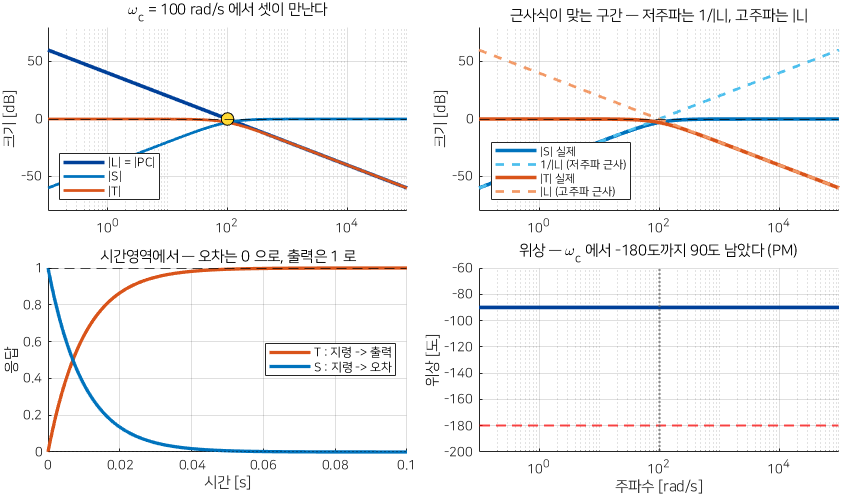

모터 루프의 L, S, T 와 시간응답

**그림 파일** `w11a_lst.png` — `make_figures.m` 의 `fig_w11a_lst` · 다시 만들려면 `make_figures('w11a_lst')`

**직접 확인해 보려면** — `W11A_01_L_S_T.m` 의 **3절**

그림 해석

오른쪽 아래가 특히 중요합니다. 위상이 어디서나 $-90$ 도이므로 **위상여유가 정확히 90 도**입니다. 그리고 위상이 $-180$ 도에 **절대 닿지 않으므로** 이득여유는 무한입니다. 이득을 몇 배로 올려도 불안정해지지 않습니다.

[Gm_m, Pm_m, ~, wc_m] = margin(Lm_min);
table(20*log10(Gm_m), Pm_m, wc_m, bandwidth(Tm), ...
    'VariableNames', {'GM_dB', 'PM_deg', 'wc_rad_s', 'wb_rad_s'})

`Inf`, $90.0$ 도, $100.0$ rad/s, $100.0$ rad/s — 네 숫자가 전부 손으로 예측한 값과 같습니다.

왜 중요한가 — 이런 루프는 **이상적으로 좋습니다.** 위상여유 90 도, 이득여유 무한, 오버슈트 0 %. 그런데 실제 설계에서 이렇게 되는 일은 거의 없습니다. 플랜트에 극점이 두세 개 더 있으면 위상이 $-180$ 도를 넘어가기 때문입니다. 11B 주차에서 그 현실적인 경우를 다룹니다. 오늘은 **좋은 루프가 어떤 모양인지** 먼저 눈에 익히는 것이 목적입니다.

## 3. 네 숫자 — $\omega_c$, GM, PM, $\omega_b$

왜 필요한가 — 루프의 모양을 말로 설명할 수는 없습니다. **숫자 네 개로** 요약해야 서로 비교하고 사양과 대조할 수 있습니다. 10주차에서 GM 과 PM 을 배웠고, 오늘 $\omega_c$ 와 $\omega_b$ 를 추가해서 네 개를 완성합니다.

먼저 네 개를 한 표에 모아 둡니다. 각각은 아래 절에서 자세히 봅니다.

가장 많이 헷갈리는 것 — $\omega_c$** 는 개루프에서, **$\omega_b$** 는 폐루프에서 읽습니다.** 두 개는 다른 그림에서 나오는 다른 숫자입니다. 그런데 값이 비슷해서 자꾸 섞입니다. 3-3 절에서 왜 비슷한지, 얼마나 다른지 정확히 봅니다.

## 3-1. 교차주파수 $\omega_c$ — 속도의 척도

정의는 간단합니다. **개루프 크기가 1 (= 0 dB) 이 되는 주파수**입니다.


$$|L(j\omega_c)| = 1 \qquad \text{즉} \qquad |L(j\omega_c)|_{dB} = 0$$


왜 이 주파수가 특별한가 — 1-3 절의 표를 다시 봅니다.

- $\omega < \omega_c$ 에서는 $|L| > 1$ 이므로 되먹임이 **일하고 있습니다**

- $\omega > \omega_c$ 에서는 $|L| < 1$ 이므로 되먹임이 **손을 놓습니다**

즉 $\omega_c$ 는 **되먹임이 효력을 갖는 구간의 끝**입니다. 이 주파수가 높으면 더 넓은 범위의 신호에 되먹임이 작동하니 응답이 빠릅니다.

손으로 구하는 법 — $L = 100/s$ 라면 $|L(j\omega)| = 100/\omega$ 입니다. 이것이 1 이 되는 곳을 찾습니다.


$$\frac{100}{\omega_c} = 1 \quad \Longrightarrow \quad \omega_c = 100 \;\text{rad/s}$$


암산으로 됩니다. 일반적으로 적분기 하나뿐인 루프 $L = K/s$ 에서는 $\omega_c = K$ 입니다. 이득을 그대로 읽으면 교차주파수입니다. 기억해 둘 만한 관계입니다.

## 3-2. 이득여유와 위상여유 — 왜 하나가 아니라 둘인가

왜 필요한가 — 10주차에서 두 여유의 정의를 배웠습니다. 여기서는 **설계자의 시선으로** 다시 봅니다. "왜 숫자가 두 개나 필요한가" 에 답하는 것이 목표입니다.

정의를 다시 적습니다.

- **위상여유** PM — $\omega_c$ 에서 위상이 $-180$ 도까지 **몇 도 남았는가**


$$\text{PM} = 180^\circ + \angle L(j\omega_c)$$


- **이득여유** GM — 위상이 $-180$ 도가 되는 주파수 $\omega_{180}$ 에서 크기를 **몇 배 올리면** 1 이 되는가


$$\text{GM} = \frac{1}{|L(j\omega_{180})|}, \qquad \text{GM}_{dB} = -|L(j\omega_{180})|_{dB}$$


두 여유는 **나이퀴스트 선도에서 **$-1$** 점까지의 거리를 두 방향으로 잰 것**입니다.

그래서 둘 다 필요합니다. 이득은 맞는데 지연이 생기는 경우(디지털 제어기가 그렇습니다)에는 GM 이 아무리 커도 PM 이 없으면 발산합니다. 반대도 마찬가지입니다.

$\omega_c$** 에서의 기울기가 PM 을 결정합니다.** 이것이 설계에서 가장 실용적인 규칙입니다. 보드 선도에서 기울기와 위상은 묶여 있기 때문입니다 (9주차).

0 절 그림에서 가운데 띠를 "$-20$ dB/decade 로 완만하게" 지나가라고 한 이유가 이것입니다. **급하게 떨어뜨리면 위상여유가 사라집니다.**

세 기울기를 직접 만들어 확인합니다.

L1 = 100/s;                       % -20 dB/dec
L2 = 100/s^2 * 10;                % -40 dB/dec
L3 = 100/s^3 * 100;               % -60 dB/dec
nm = {'-20 dB/dec'; '-40 dB/dec'; '-60 dB/dec'};
pmv = zeros(3,1); wcv = zeros(3,1);
Lcell = {L1, L2, L3};
for k = 1:3
    [~, pmv(k), ~, wcv(k)] = margin(Lcell{k});
end
table(nm, wcv, pmv, 'VariableNames', {'기울기', 'wc_rad_s', 'PM_deg'})

기울기가 급해질 때마다 PM 이 90 도씩 줄어듭니다. $-40$ dB/decade 에서는 PM 이 0 도, 즉 경계입니다. 표의 규칙이 그대로 나왔습니다.

왜 중요한가 — 11B 주차에서 Lead 보상기를 쓰는 이유가 바로 이것입니다. 저주파 이득을 벌려고 $|L|$ 을 올리면 $\omega_c$ 가 오른쪽으로 밀리면서 기울기가 급한 구간으로 들어가 PM 이 사라집니다. Lead 는 그 자리의 기울기를 다시 눕혀 주는 도구입니다.

## 3-3. 대역폭 $\omega_b$ — $\omega_c$ 와 다른 것인데 거의 같다

왜 필요한가 — 사양서에는 보통 "대역폭 50 Hz 이상" 처럼 적혀 있습니다. 그런데 설계할 때 보는 것은 $\omega_c$ 입니다. 둘을 번역할 수 있어야 합니다.

**정의부터 정확히.** 대역폭은 **폐루프** $T$ 에서 읽습니다.


$$|T(j\omega_b)| = \frac{1}{\sqrt{2}} \approx 0.707 \qquad \text{즉} \qquad |T|_{dB} = -3 \;\text{dB}$$


왜 $-3$ dB 인가 — 크기가 $1/\sqrt{2}$ 이면 **전력이 절반**입니다 ($(1/\sqrt{2})^2 = 1/2$). 통신에서 온 관습인데 제어에서도 그대로 씁니다.

뜻 — **"이 주파수까지의 정현파 지령은 따라갈 수 있다"** 는 경계입니다. $\omega_b$ 보다 빠른 지령은 크기가 절반 이하로 줄어서 나옵니다. 담당교수 강의자료의 표현을 그대로 옮기면 "추종할 수 있는 최대 주파수의 정현파" 입니다.

그리고 **대역폭은 빠르기의 척도**입니다. 상승시간·첨두시간과 반비례합니다. 4주차에서 배운 $t_r \approx 1.8/\omega_n$ 과 같은 종류의 관계입니다.

두 숫자의 차이를 표로 못 박아 둡니다.

왜 비슷한가 — $\omega_c$ 에서 $|L| = 1$ 이므로 $|T| = |L/(1+L)|$ 은 $|1/(1+L)|$ 입니다. $L$ 의 위상에 따라 다르지만 대략 $0.5 \sim 1.3$ 사이, 즉 $-6 \sim +2$ dB 범위입니다. $-3$ dB 선과 멀지 않습니다. 그래서 두 주파수가 가까이 붙습니다.

`bandwidth` 명령을 정리합니다.

- **원리** — 폐루프 주파수응답을 계산해 DC 이득보다 3 dB 낮아지는 첫 주파수를 찾습니다

- **입력** — **폐루프** 전달함수. `feedback` 으로 닫아 놓은 것을 넣습니다

- **출력** — 주파수 하나 [rad/s]

- **주의 1** — 개루프를 넣으면 전혀 다른 숫자가 나옵니다. 가장 흔한 실수입니다

- **주의 2** — DC 이득이 1 이 아니면 기준이 DC 이득 대비 $-3$ dB 입니다. 절대값 $-3$ dB 가 아닙니다. 둘째 인수로 기준을 바꿀 수 있습니다

- **예제** — 아래에서 모터 루프로 확인합니다

table(wc_m, bandwidth(Tm), bandwidth(Tm)/wc_m, ...
    'VariableNames', {'wc_rad_s', 'wb_rad_s', '비율'})

모터 루프는 $\omega_c = \omega_b = 100$ 으로 **정확히 같습니다.** 이것은 $T$ 가 1차 저역통과 $100/(s+100)$ 이기 때문에 생긴 특별한 경우입니다. 1차 저역통과의 $-3$ dB 주파수는 꺾이는 주파수와 같습니다. 일반적으로는 다릅니다.

## 3-3-1. 2차 표준루프로 두 식을 손으로 유도한다

왜 필요한가 — "$\omega_b \approx 1.5\,\omega_c$" 라는 어림셈은 어디서 나온 것인지 확인해 둬야 합니다. 2차 표준형에서는 두 주파수를 **정확히** 계산할 수 있습니다.

4주차의 표준 2차 폐루프를 만드는 개루프는 이것입니다.


$$L(s) = \frac{\omega_n^2}{s\,(s + 2\zeta\omega_n)}$$


확인 — $T = L/(1+L) = \frac{\omega_n^2}{s^2 + 2\zeta\omega_n s + \omega_n^2}$ 로 4주차의 표준형이 정확히 나옵니다.

$\omega_c$** 유도.** $|L(j\omega)| = 1$ 을 풉니다.


$$|L(j\omega)| = \frac{\omega_n^2}{\omega \sqrt{\omega^2 + 4\zeta^2\omega_n^2}} = 1$$


양변을 제곱하고 정리합니다.


$$\omega_n^4 = \omega^2 (\omega^2 + 4\zeta^2 \omega_n^2) = \omega^4 + 4\zeta^2\omega_n^2 \omega^2$$


$x = \omega^2$ 로 놓으면 2차방정식입니다.


$$x^2 + 4\zeta^2\omega_n^2 x - \omega_n^4 = 0$$


근의 공식으로 양수 근만 취합니다.


$$x = \frac{-4\zeta^2\omega_n^2 + \sqrt{16\zeta^4\omega_n^4 + 4\omega_n^4}}{2} = \omega_n^2\left(\sqrt{1 + 4\zeta^4} - 2\zeta^2\right)$$


제곱근을 씌우면 끝입니다.


$$\omega_c = \omega_n \sqrt{\sqrt{1 + 4\zeta^4} - 2\zeta^2}$$


$\omega_b$** 유도.** 같은 방식으로 $|T(j\omega)| = 1/\sqrt{2}$ 를 풉니다. 표준 2차 폐루프의 크기는 이렇습니다.


$$|T(j\omega)| = \frac{\omega_n^2}{\sqrt{(\omega_n^2 - \omega^2)^2 + (2\zeta\omega_n\omega)^2}}$$


제곱해서 $1/2$ 로 놓고 $u = (\omega/\omega_n)^2$ 로 정규화하면


$$(1-u)^2 + 4\zeta^2 u = 2 \quad \Longrightarrow \quad u^2 - (2 - 4\zeta^2) u - 1 = 0$$



$$u = (1 - 2\zeta^2) + \sqrt{(1-2\zeta^2)^2 + 1}$$


루트 안을 펼치면 $2 - 4\zeta^2 + 4\zeta^4$ 입니다. 따라서


$$\omega_b = \omega_n \sqrt{1 - 2\zeta^2 + \sqrt{2 - 4\zeta^2 + 4\zeta^4}}$$


두 식을 MATLAB 실측과 대조합니다. $\omega_n = 1$ 로 두면 비율이 바로 보입니다.

zv = [0.1 0.2 0.3 0.4 0.5 1/sqrt(2) 0.8 0.9 1.0]';
wc_f = sqrt(sqrt(1 + 4*zv.^4) - 2*zv.^2);
wb_f = sqrt(1 - 2*zv.^2 + sqrt(2 - 4*zv.^2 + 4*zv.^4));
wc_mea = zeros(size(zv)); wb_mea = zeros(size(zv)); pm_mea = zeros(size(zv));
for k = 1:numel(zv)
    Lk = 1/(s*(s + 2*zv(k)));                  % wn = 1
    [~, pm_mea(k), ~, wc_mea(k)] = margin(Lk);
    wb_mea(k) = bandwidth(feedback(Lk, 1));
end
table(zv, wc_f, wc_mea, wb_f, wb_mea, wb_f./wc_f, ...
    'VariableNames', {'zeta', 'wc_식', 'wc_실측', 'wb_식', 'wb_실측', '비율'})

식과 실측이 소수 넷째 자리까지 같습니다. 유도가 맞았습니다.

표에서 읽을 것 세 가지입니다.

- $\zeta = 0.707$** 에서 **$\omega_b = 1.0000\,\omega_n$ 입니다. 정확히 1 입니다. 기억하기 좋은 기준점입니다

- 비율 $\omega_b/\omega_c$ 는 $1.32 \sim 1.62$ 사이에 있습니다. $\zeta = 0.5$ 근처에서 최대 1.62 입니다

- 그래서 **"**$\omega_b$** 는 **$\omega_c$** 의 1.5 배 정도"** 라고 외워 두면 실용적으로 충분합니다

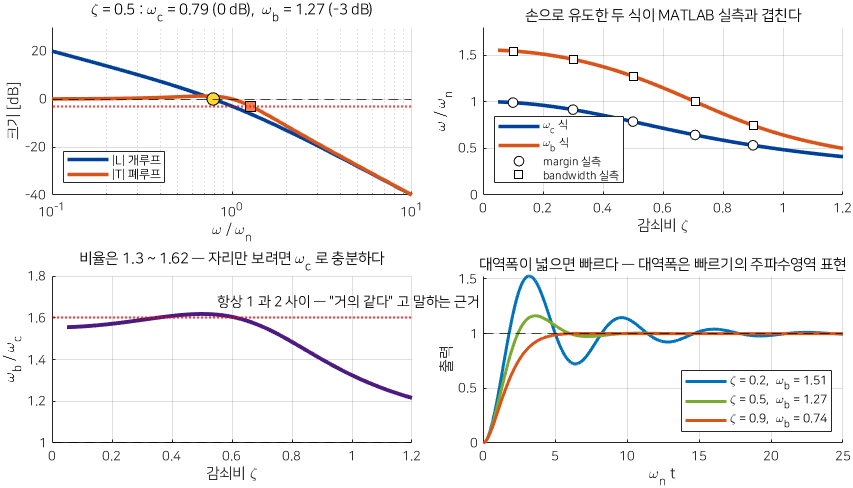

교차주파수와 대역폭 — 다른 것인데 거의 같다

**그림 파일** `w11a_wc_wbw.png` — `make_figures.m` 의 `fig_w11a_wc_wbw` · 다시 만들려면 `make_figures('w11a_wc_wbw')`

**직접 확인해 보려면** — `W11A_02_margins_bandwidth.m` 의 **3절**

그림 해석

왜 중요한가 — 사양이 "$\omega_b \ge 60$ rad/s" 로 오면 설계 목표를 $\omega_c \ge 40$** rad/s** 로 번역해서 보드 선도에서 바로 확인할 수 있습니다. 11B 주차의 설계 1단계가 정확히 이 작업입니다.

## 3-4. 위상여유와 감쇠비 — 공식은 없지만 규칙은 있다

왜 필요한가 — 사양은 보통 시간영역으로 옵니다. "오버슈트 20 % 이하". 그런데 설계는 주파수영역에서 합니다. 둘을 잇는 다리가 **PM 과 **$\zeta$** 의 관계**입니다.

먼저 분명히 해 둘 것 — **PM 과 **$\zeta$** 사이에 닫힌 형태의 공식은 없습니다.** $\omega_c$ 식을 PM 정의에 넣으면 이런 식이 나옵니다.


$$\text{PM} = 90^\circ - \arctan\frac{\sqrt{\sqrt{1+4\zeta^4} - 2\zeta^2}}{2\zeta}$$


이 식을 $\zeta$ 에 대해 뒤집을 수가 없습니다. 그래서 **어림셈**을 씁니다. 그런데 다행히 이 관계가 거의 직선입니다.


$$\zeta \;\approx\; \frac{\text{PM}}{100}$$


PM 을 도(degree) 로 넣습니다. PM 50 도면 $\zeta \approx 0.5$, PM 70 도면 $\zeta \approx 0.7$ 입니다. 외우기 쉽습니다.

얼마나 맞는지 직접 재 봅니다.

rule1 = pm_mea/100;
err1  = rule1 - zv;
table(zv, pm_mea, rule1, err1, ...
    'VariableNames', {'zeta_실제', 'PM_deg', 'PM_나누기_100', '오차'})

오차가 전 구간에서 $\pm 0.06$ 안입니다. **설계 1단계의 값을 정하는 데는 충분합니다.** 정확한 값은 설계 후 `stepinfo` 로 재면 됩니다.

참고 — 문헌에는 중간 구간용으로 $\zeta \approx 0.01\,(\text{PM} - 4^\circ)$ 라는 보정식도 나옵니다. PM 15 도에서 55 도 사이에서 더 맞다고 되어 있지만, 위 표의 2차 표준루프에서는 $\text{PM}/100$ 이 더 맞습니다. 루프의 형태에 따라 달라지므로 **어느 쪽이든 어림셈이라는 것을 잊지 않는 것**이 중요합니다.

어림셈이 통하는 조건도 적어 둡니다.

- 최소위상 시스템 (우반평면 영점이 없다)

- **지배 극점 쌍**이 뚜렷하다 (다른 극점이 훨씬 멀리 있다)

- $\omega_c$ 근처에서 $|L|$ 이 $-20$ dB/decade 로 완만하다

조건을 벗어나면 PM 은 넉넉한데 응답이 이상한 일이 생깁니다. 그래서 **주파수영역에서 설계하고 시간영역에서 확인하는** 두 단계가 항상 필요합니다.

어긋나는 방식이 구체적으로 세 가지 있습니다. 세 루프 모두 PM 은 $40 \sim 52$ 도로 비슷하게 좋아 보입니다. 어림셈으로 얻은 $\zeta$ 에 4주차의 오버슈트 공식을 넣어 **예측**을 만들고, 실제 계단응답의 **실측**과 맞대 본 것입니다.

셋째 줄이 가장 위험합니다. 오버슈트가 0 이라서 계단응답만 짧게 보면 완벽해 보이는데, 폐루프 극점 중 감쇠비가 $0.017$ 인 것이 하나 있어서 $40$ 초가 지나도 잔물결이 남습니다. **PM 은 교차주파수 한 점만 보는 숫자**이므로, 교차주파수에서 멀리 떨어진 공진은 PM 에 전혀 나타나지 않습니다.

확인하는 방법은 두 가지입니다.

- `damp(T)` 로 폐루프 극점의 감쇠비를 **전부** 본다. 가장 작은 값이 기준이다

- 계단응답을 **충분히 길게** 본다 (위 셋째 루프는 $40$ 초가 필요하다)

실습은 `W11A_03_pm_zeta.m` 의 **3절**입니다. 세 응답을 나란히 그려 줍니다.

## 3-4-1. 사양을 번역하는 사슬 — 오버슈트에서 PM 까지

왜 필요한가 — 이제 조각이 다 모였습니다. 시간 사양을 주파수 목표로 바꾸는 전체 사슬을 한 번에 이어 봅니다. 11B 주차에서 매번 쓰는 절차입니다.

사슬은 네 칸입니다.

예제로 "오버슈트 10 % 이하, 정착시간 0.5 초 이하" 를 번역합니다.

OS_req = 10;  ts_req = 0.5;
lnOS  = log(OS_req/100);
z_req = -lnOS/sqrt(pi^2 + lnOS^2);
PM_req = 100*z_req;
wn_req = 4/(z_req*ts_req);
wc_req = wn_req*sqrt(sqrt(1 + 4*z_req^4) - 2*z_req^2);
wb_req = wn_req*sqrt(1 - 2*z_req^2 + sqrt(2 - 4*z_req^2 + 4*z_req^4));
table(z_req, PM_req, wn_req, wc_req, wb_req, ...
    'VariableNames', {'zeta', 'PM_deg', 'wn', 'wc_목표', 'wb_예상'})

결과를 설계 목표로 쓰면 이렇게 읽습니다.

- **위상여유 59 도 이상** 확보할 것

- **교차주파수 11 rad/s 이상** 으로 밀 것

번역이 맞는지 거꾸로 확인합니다. 이 $\zeta$, $\omega_n$ 으로 2차 루프를 만들어 실제 오버슈트와 정착시간을 재 봅니다.

Lreq = wn_req^2/(s*(s + 2*z_req*wn_req));
si = stepinfo(feedback(Lreq, 1));
[~, pm_chk, ~, wc_chk] = margin(Lreq);
table(si.Overshoot, si.SettlingTime, pm_chk, wc_chk, ...
    'VariableNames', {'실제_OS_퍼센트', '실제_ts_초', '실제_PM_deg', '실제_wc'})

오버슈트 10.0 %, 정착시간 0.5 초 근처로 사양을 만족합니다. PM 도 어림셈 59 도와 비슷한 값이 나옵니다. 사슬이 작동합니다.

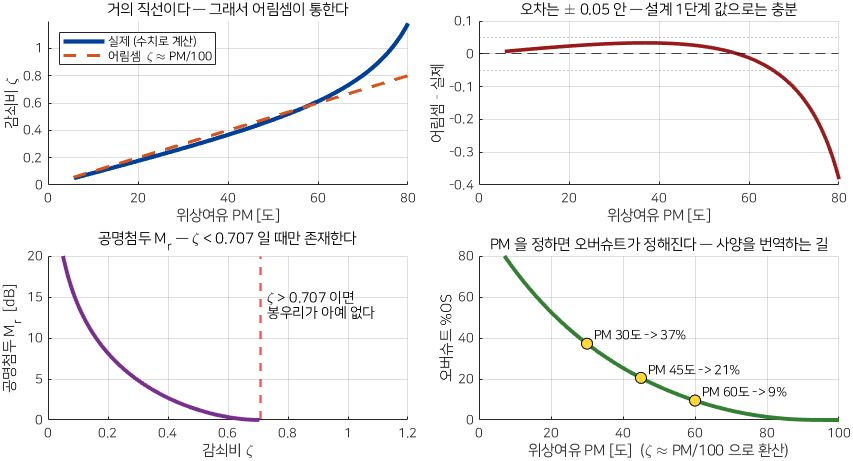

위상여유와 감쇠비 — 거의 직선 관계

**그림 파일** `w11a_pm_zeta.png` — `make_figures.m` 의 `fig_w11a_pm_zeta` · 다시 만들려면 `make_figures('w11a_pm_zeta')`

**직접 확인해 보려면** — `W11A_03_pm_zeta.m` 의 **2절**

그림 해석

오른쪽 아래의 세 점은 외워 둘 만합니다.

## 3-4-2. 공명첨두 $M_r$ — 주파수영역에서 보는 날카로움

왜 필요한가 — 오버슈트는 시간영역의 날카로움입니다. 주파수영역에도 같은 것이 있습니다. 폐루프 $|T|$ 의 **봉우리 높이**입니다.


$$M_r = \max_\omega |T(j\omega)|$$


표준 2차계에서는 손으로 구할 수 있습니다. $|T|$ 를 미분해서 0 이 되는 주파수를 찾으면 됩니다. 결과만 적습니다 (유도는 4주차 오버슈트 공식과 같은 방식입니다).


$$M_r = \frac{1}{2\zeta\sqrt{1 - \zeta^2}}, \qquad \omega_r = \omega_n\sqrt{1 - 2\zeta^2} \qquad (\zeta < 0.707)$$


$\zeta \ge 0.707$** 이면 봉우리가 아예 없습니다.** 루트 안이 음수가 되기 때문입니다. 이 경우 $|T|$ 는 단조감소하고 $M_r = 1$ (0 dB) 입니다.

손계산과 실측을 대조합니다. 유효 구간 밖($\zeta \ge 0.7071$)은 **식을 계산하지 않고 비워 둡니다.** 봉우리가 없는데 "봉우리 높이" 를 묻는 것이 되기 때문입니다. 그냥 계산하면 식은 $M_r > 1$ 을 주는데 실측은 1 이어서 서로 어긋납니다.

zr = [0.2 0.4 0.5 0.6 0.707 0.8]';
yes = zr < 1/sqrt(2);
Mr_f = nan(size(zr));  wr_f = nan(size(zr));
Mr_f(yes) = 1./(2*zr(yes).*sqrt(1 - zr(yes).^2));
wr_f(yes) = sqrt(1 - 2*zr(yes).^2);
Mr_mea = zeros(size(zr)); wr_mea = zeros(size(zr));
for k = 1:numel(zr)
    Tk = feedback(1/(s*(s + 2*zr(k))), 1);
    [mg, wg] = getPeakGain(Tk);
    Mr_mea(k) = mg;  wr_mea(k) = wg;
end
table(zr, Mr_f, Mr_mea, 20*log10(Mr_mea), wr_f, wr_mea, ...
    'VariableNames', {'zeta', 'Mr_식', 'Mr_실측', 'Mr_dB', 'wr_식', 'wr_실측'})

읽는 법

- $\zeta$ 가 $0.6$ 까지는 식과 실측이 소수 넷째 자리까지 같습니다

- $\zeta = 0.707$ 은 **경계**입니다. 식은 $\omega_r = 0.0174$ 라는 아주 작은 값을 주고 실측은 0 을 줍니다. 봉우리가 막 사라지는 지점이라 그렇습니다

- $\zeta = 0.8$ 은 빈칸(`NaN`)입니다. 봉우리가 없으니 $M_r$ 은 그냥 1 (0 dB) 입니다

**공식에는 유효 구간이 붙어 있습니다.** 구간을 적어 두지 않은 공식을 그대로 계산해서 숫자가 나왔다고 믿는 것이 가장 흔한 실수입니다.

실용적 기준 — $M_r \le 2$** (6 dB) 이하로 유지**합니다. 이것은 $\zeta \ge 0.26$, 즉 PM 26 도 이상에 해당합니다. $M_r$ 이 크면 그 주파수의 외란이나 잡음이 **증폭되어** 나옵니다.

세 가지 날카로움 지표를 한 표에 모아 둡니다. 전부 같은 것을 다르게 본 것입니다.

## 4. 주파수 띠 세 개 — 요구사항을 나눠 싣는다

왜 필요한가 — 1-2 절에서 $S + T = 1$ 때문에 모든 것을 동시에 가질 수 없다는 것을 봤습니다. 해법은 **주파수마다 다른 것을 요구하는 것**이었습니다. 이제 그것을 구체적인 설계 지침으로 정리합니다. 담당교수 강의자료의 세 영역 구분을 그대로 따릅니다.

0 절의 그림을 다시 봅니다. 그 세 띠가 이것입니다.

각 띠를 하나씩 봅니다.

**저주파 띠 — **$|L|$** 을 크게.** 1-3 절에서 $|S| \approx 1/|L|$ 이었습니다. 저주파 외란을 40 dB 줄이려면 그 주파수에서 $|L| \ge 40$ dB 가 필요합니다. 정상상태오차도 같은 이야기입니다. $s \to 0$ 에서 $|L| \to \infty$ 면 ($=$ 적분기가 있으면) 계단 오차가 0 이 됩니다 (5주차).

**중간 띠 — 완만하게.** 3-2 절에서 기울기가 PM 을 결정한다고 했습니다. 저주파에서 올린 이득을 고주파로 내려야 하는데, **그 내려오는 길이 **$\omega_c$** 를 지나갈 때만 완만하면** 됩니다. 저주파에서 아무리 급하게 올려 놓았어도 괜찮습니다.

**고주파 띠 — 작게.** 1-3 절에서 $|T| \approx |L|$ 이었습니다. 6절에서 보겠지만 센서 잡음은 $T$ 를 타고 들어옵니다. 그러니 고주파에서 $|L|$ 을 떨어뜨리는 것이 곧 잡음 차단입니다. 그리고 모델에 없는 고주파 동특성 (모터 축의 비틀림 진동 같은 것) 이 있어도 $|L|$ 이 작으면 불안정해지지 않습니다.

모터 루프가 이 지침을 만족하는지 확인합니다.

chk_w = [1 10 100 1000 1e4]';
chk = table(chk_w, ...
    20*log10(squeeze(abs(freqresp(Lm_min, chk_w)))), ...
    20*log10(squeeze(abs(freqresp(Sm, chk_w)))), ...
    20*log10(squeeze(abs(freqresp(Tm, chk_w)))), ...
    'VariableNames', {'w_rad_s', 'L_dB', 'S_dB', 'T_dB'})

읽으면 이렇습니다.

- $\omega = 1$ : $|L| = 40$ dB 로 충분히 크다. 저주파 외란을 $1/100$ 로 줄인다

- $\omega = 100$ : 0 dB 통과. 기울기가 $-20$ dB/dec 이므로 PM 90 도

- $\omega = 10^4$ : $|T| = -40$ dB. 이 주파수 잡음은 $1/100$ 만 들어온다

세 띠 모두 합격입니다. 좋은 루프입니다.

왜 중요한가 — 11B 주차의 종합 설계에서 사양 다섯 개를 다섯 단계로 나눠 맞추는데, **그 나눔의 기준이 바로 이 세 띠**입니다. 어떤 사양이 어느 띠의 문제인지 알아보는 것이 설계의 첫걸음입니다.

## 5. 왜 되먹임인가 — 외란이 답한다

왜 필요한가 — 1주차에서 "되먹임을 하면 좋다" 고 배웠습니다. 그런데 **왜** 좋은지 가장 선명하게 답하는 것이 외란입니다. 그리고 그 답은 주파수영역에서만 제대로 보입니다.

먼저 외란이 **어디로 들어오는가** 를 구분해야 합니다. 들어오는 자리가 다르면 전달함수가 달라집니다.

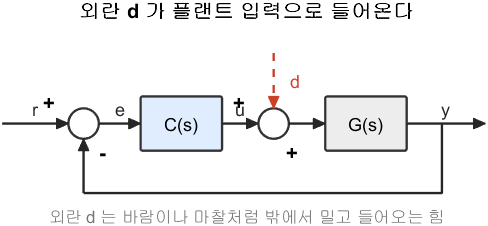

외란이 플랜트 입력에 들어가는 폐루프

**그림 파일** `loop_disturbance.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_disturbance')`

그림 해석

이 자리에 들어오는 것을 **입력외란**(input disturbance) $d_i$ 라고 합니다. 출력 쪽에 바로 더해지는 것은 **출력외란**(output disturbance) $d_o$ 입니다. 둘을 나눠서 봅니다.

## 5-1. 출력외란 — 전달함수가 바로 $S$ 다

출력에 직접 더해지는 경우입니다. 센서가 보는 값이 $y = (\text{플랜트 출력}) + d_o$ 인 상황입니다. 측정 오프셋이나 외부에서 밀리는 힘이 이에 해당합니다.

신호를 따라갑니다. 지령은 0 으로 둡니다 ($r = 0$, 외란만 보기 위해).


$$y = P u + d_o, \qquad u = C e, \qquad e = -y$$


대입합니다.


$$y = P C (-y) + d_o$$


$y$ 를 한쪽으로 모읍니다.


$$(1 + PC)\, y = d_o \quad \Longrightarrow \quad \frac{y}{d_o} = \frac{1}{1+L} = S$$


**출력외란에 대한 전달함수가 감도함수 **$S$** 그 자체입니다.** 그래서 $S$ 를 작게 만드는 것이 곧 외란 억제입니다. 1-2 절에서 $|S|$ 를 저주파에서 작게 하라고 한 이유가 이것입니다.

개루프와 비교하면 차이가 분명합니다. 되먹임이 없으면 $e = r$ 이므로 $u = Cr$ 이고, $y = PCr + d_o$ 입니다. 즉


$$\left.\frac{y}{d_o}\right|_{\text{개루프}} = 1$$


**외란이 그대로 출력에 나옵니다.** 제어기를 어떻게 설계해도 1 입니다.

담당교수 강의자료의 표현을 옮기면 "$L(s)$ 가 크면 $1/L(s)$ 가 작은 수가 되므로 외란이 잘 억제된다" 그리고 "고주파 영역의 외란은 억제할 수 없다" 입니다. 후자는 고주파에서 $|L| < 1$ 이므로 $|S| \approx 1$ 이 되기 때문입니다.

## 5-2. 입력외란 — 개루프는 손쓸 방법이 아예 없다

왜 필요한가 — 출력외란은 개루프에서 $1$ 이라 좀 추상적입니다. 입력외란이 되먹임의 가치를 훨씬 선명하게 보여 줍니다. 그리고 실제 시스템의 외란은 대부분 입력 쪽에 있습니다 (부하 토크, 바람, 마찰).

위 그림의 구조입니다. 플랜트가 받는 것은 $u + d_i$ 입니다. $r = 0$ 으로 둡니다.


$$y = P(u + d_i), \qquad u = C e = -C y$$


대입합니다.


$$y = P(-Cy + d_i) = -PC y + P d_i$$


$y$ 를 모읍니다.


$$(1 + PC)\, y = P\, d_i \quad \Longrightarrow \quad \frac{y}{d_i} = \frac{P}{1 + L} = P\,S$$


개루프는 어떤가요. 되먹임이 없으니 $u$ 는 $y$ 와 무관합니다. $r=0$ 이면 $u=0$ 이고


$$\left.\frac{y}{d_i}\right|_{\text{개루프}} = P$$


**두 식을 나란히 놓고 보십시오.**


$$\left.\frac{y}{d_i}\right|_{\text{개루프}} = P \qquad \text{vs} \qquad \left.\frac{y}{d_i}\right|_{\text{폐루프}} = \frac{P}{1+L}$$


차이는 **분모의 **$1 + L$** 뿐**입니다. 그런데 이것이 결정적입니다.

- 개루프에는 $C$ 가 **아예 나타나지 않습니다.** 제어기를 아무리 잘 설계해도 $y/d_i = P$ 입니다. 담당교수 강의자료의 표현 그대로 **"제어기를 얼마나 잘 설계하든 **$d_i$** 가 **$y$** 에 미치는 영향을 줄일 수 없다"**

- 폐루프에서는 $|L|$ 을 올리는 만큼 그대로 나누어집니다

**이것이 "왜 되먹임인가" 에 대한 가장 정직한 답입니다.** 되먹임이 아니면 입력외란에 대해 할 수 있는 일이 없습니다.

수치로 확인합니다. 모터 루프에서 네 주파수의 외란을 비교합니다.

wd = [0.1 2 2*pi 100]';
open_dB   = 20*log10(squeeze(abs(freqresp(Pm, wd))));
closed_dB = 20*log10(squeeze(abs(freqresp(Pm*Sm, wd))));
table(wd, open_dB, closed_dB, open_dB - closed_dB, ...
    'VariableNames', {'w_rad_s', '개루프_dB', '폐루프_dB', '되먹임이_번_dB'})

마지막 열이 되먹임의 이득입니다.

- $\omega = 0.1$ : **60 dB** (1000 배) 좋아진다. $|L(0.1)| = 60$ dB 와 같다

- $\omega = 2$ : 34 dB

- $\omega = 2\pi$ : 24 dB

- $\omega = 100$ : **3 dB 뿐이다.** 여기가 $\omega_c$ 이므로 $|L| = 1$, 즉 $|1+L| \approx \sqrt{2}$ 밖에 안 된다

**되먹임이 버는 양이 정확히 **$|1 + L|$** 입니다.** $\omega_c$ 를 넘으면 되먹임은 아무것도 해 주지 않습니다. 이것이 4절에서 "고주파 외란은 억제할 수 없다" 고 한 것의 수치적 근거입니다.

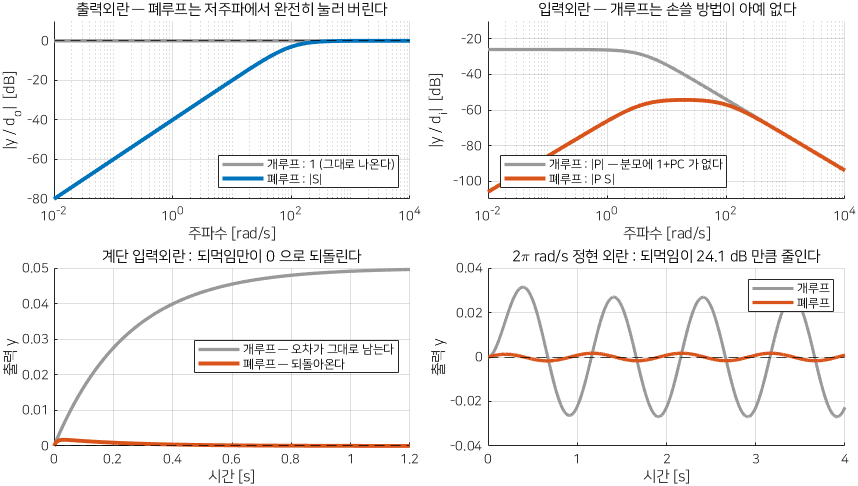

외란 — 개루프와 폐루프의 결정적 차이

**그림 파일** `w11a_dist.png` — `make_figures.m` 의 `fig_w11a_dist` · 다시 만들려면 `make_figures('w11a_dist')`

**직접 확인해 보려면** — `W11A_04_disturbance_noise.m` 의 **1절**과 **2절**

그림 해석

## 5-3. 손계산 $-24.05$ dB 를 Simulink 와 대조한다

왜 필요한가 — 담당교수 강의자료의 Simulink 예제에 외란 감쇠량이 $-24.0541$ dB 로 적혀 있습니다. 그 숫자가 어디서 나온 것인지 손으로 확인하고, 직접 시뮬레이션해서 맞춰 보겠습니다. **같은 답을 세 가지 방법으로 구하는** 연습입니다.

강의자료의 외란은 $\omega = 2\pi$ rad/s (즉 1 Hz) 정현파이고 출력 쪽에 들어갑니다. 그러니 5-1 절의 $y/d_o = S$ 를 쓰면 됩니다.

**방법 1 — 손계산.** 2-1 절의 식에 $\omega = 2\pi$ 를 넣습니다.


$$|S(j2\pi)| = \frac{2\pi}{\sqrt{(2\pi)^2 + 100^2}} = \frac{6.2832}{\sqrt{39.478 + 10000}} = \frac{6.2832}{100.197}$$



$$= 0.062708 \quad \Longrightarrow \quad 20\log_{10}(0.062708) = -24.05 \;\text{dB}$$


w_d = 2*pi;
hand = w_d/sqrt(w_d^2 + 100^2);

**방법 2** — `freqresp` 로 재기.

mat = abs(freqresp(Sm, w_d));

**방법 3 — 시간영역 시뮬레이션.** 정현 외란을 넣고 정상상태 진폭을 잽니다.

td = (0:1e-4:6)';
yd = lsim(Sm, sin(w_d*td), td);
amp = max(yd(td > 4));                       % 과도응답이 끝난 뒤의 진폭
table([hand; mat; amp], 20*log10([hand; mat; amp]), ...
    'RowNames', {'손계산', 'freqresp', 'lsim_진폭'}, ...
    'VariableNames', {'크기', 'dB'})

세 방법 모두 $-24.05$ dB 입니다. 강의자료의 `DB = -24.0541` 과 같습니다.

방법마다 덤으로 주는 것이 다릅니다.

왜 중요한가 — 주파수영역의 숫자가 시간영역의 눈에 보이는 진폭과 정확히 맞아떨어진다는 것을 한 번 확인해 두면, 앞으로 보드 선도를 **믿고** 설계할 수 있습니다. `W11A_05_run_simulink.m` 에서 같은 것을 Simulink 모델로 한 번 더 확인합니다.

## 5-4. 더 줄이려면 — PI 의 꺾이는 자리를 옮긴다

왜 필요한가 — 지금까지는 주어진 제어기를 **분석**했습니다. 이제 처음으로 **설계**를 해 봅니다. 1 Hz 외란이 $-24.05$ dB 로 줄었는데, 이것이 부족하다고 하면 무엇을 어떻게 바꿔야 하는가. 이 한 번의 선택이 루프 성형의 전부입니다.

답은 5-1 절에 이미 있습니다. $y/d_o = S \approx 1/|L|$ 이므로 **그 주파수에서 **$|L|$** 을 더 올리면** 됩니다. 문제는 "어떻게 올리는가" 입니다. 아무 데나 올리면 교차주파수가 따라 올라가 버리고, 그러면 잡음과 포화가 문제가 됩니다. **저주파만 올려야** 합니다.

그래서 PI 제어기를 담당교수 강의자료의 표기로 다시 씁니다. 지금까지 쓴 $(500s+2000)/s$ 와 **완전히 같은 식**인데, 설계에 쓰기 편한 모양입니다.


$$C(s) = K\,\frac{T_i s + 1}{T_i s}, \qquad K_i = \frac{K}{T_i}$$


두 표기가 같다는 것을 손으로 확인합니다. $K = 500$, $1/T_i = 4$ 를 넣으면


$$500 \cdot \frac{\frac{s}{4} + 1}{\frac{s}{4}} = 500 \cdot \frac{s+4}{s} = \frac{500s + 2000}{s}$$


이 모양에서 각 기호가 보드 선도의 무엇인지가 중요합니다.

즉 $1/T_i$** 를 오른쪽으로 옮기면 저주파 이득이 통째로 올라갑니다.** $K$ 는 그대로이므로 고주파는 건드리지 않습니다. 네 가지로 재 봅니다.

K_pi = 500;
invTi = [4 10 20 40]';
pm_pi = zeros(4,1); wc_pi = zeros(4,1); wb_pi = zeros(4,1);
Sd_pi = zeros(4,1); os_pi = zeros(4,1);
for k = 1:4
    Ti = 1/invTi(k);
    Ck = K_pi*(Ti*s + 1)/(Ti*s);
    Lk = minreal(Pm*Ck);
    [~, pm_pi(k), ~, wc_pi(k)] = margin(Lk);
    Tk = Lk/(1 + Lk);
    wb_pi(k) = bandwidth(Tk);
    Sd_pi(k) = 20*log10(abs(freqresp(1/(1 + Lk), 2*pi)));
    os_pi(k) = stepinfo(Tk).Overshoot;
end
table(invTi, K_pi./(1./invTi), pm_pi, wc_pi, wb_pi, Sd_pi, os_pi, ...
    'VariableNames', {'꺾이는자리', 'Ki', 'PM_deg', 'wc', 'wb', '외란_1Hz_dB', 'OS_퍼센트'})

읽는 법 — **세 열만 보면 됩니다.**

- 꺾이는 자리를 4 에서 20 으로 옮기면 1 Hz 외란이 $-24.05$ 에서 $-32.90$ dB 로 $8.85$** dB 더 줄어듭니다.** 외란이 추가로 $2.8$ 배 작아진 것입니다

- 교차주파수는 $100$ 에서 $101.8$ 로 거의 그대로입니다. **저주파만 들어올렸기 때문입니다. 이것이 루프 성형입니다**

- 대가는 PM 이 $90$ 도에서 $81$ 도로 9 도 줄고, 오버슈트가 0 에서 $8.8\,\%$ 로 생기는 것입니다. 꺾이는 자리를 40 까지 밀면 $-38.67$ dB 까지 가지만 오버슈트가 $15.6\,\%$ 가 됩니다

왜 PM 이 줄어드는가 — PI 의 위상은 항상 **음수**입니다. $0$ 에서 $-90$ 도 사이이고, 꺾이는 자리에서 $-45$ 도입니다. 꺾이는 자리를 오른쪽으로 옮기면 그 음의 위상이 $\omega_c$ 쪽으로 다가옵니다. **PI 는 저주파 이득을 사고 위상여유를 지불합니다.** 그래서 실무 지침은


$$\frac{1}{T_i} \;\approx\; \frac{\omega_c}{10}$$


입니다. 한 데케이드 떨어뜨리면 $\omega_c$ 에서의 위상 손실이 $6$ 도 이내로 남습니다. 위 표에서 $\omega_c = 100$ 이므로 $1/T_i = 10$ 이 그 지침에 해당하고, 실제로 PM 이 $86.6$ 도로 $3.4$ 도만 깎였습니다.

왜 중요한가 — 이것이 11B 주차에서 `controlSystemDesigner` 로 **마우스로** 하게 될 일입니다. 영점을 끌어 옮기면 이 표가 실시간으로 바뀝니다. 오늘은 그 표를 손으로 한 번 만들어 본 것입니다. 실습은 `W11A_04_disturbance_noise.m` 의 **1-1 절**입니다.

## 6. 공짜가 아니다 — 센서 잡음이라는 대가

왜 필요한가 — 5절까지 보면 "$|L|$ 을 크게 하면 다 좋다" 로 읽힙니다. 그런데 그러지 않는 이유가 있습니다. 되먹임을 하려면 **측정을 해야 하고**, 측정에는 잡음이 섞입니다. 그 잡음이 되먹임 선을 타고 루프 안으로 들어옵니다.

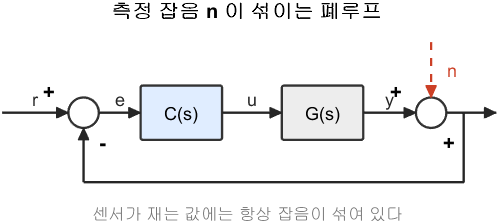

측정 잡음이 있는 폐루프

**그림 파일** `loop_noise.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_noise')`

그림 해석

신호를 따라갑니다. $r = 0$ 으로 둡니다.


$$e = -(y + n), \qquad u = Ce, \qquad y = Pu$$


대입합니다.


$$y = P C \cdot (-(y+n)) = -PC y - PC n$$


$y$ 를 모읍니다.


$$(1 + PC)\, y = -PC\, n \quad \Longrightarrow \quad \frac{y}{n} = -\frac{L}{1+L} = -T$$


**잡음에 대한 전달함수가 **$-T$** 입니다.** 부호만 다를 뿐 지령 추종 전달함수와 똑같습니다. 이것이 되먹임 제어의 근본적인 맞바꿈입니다.

**지령을 잘 따라가게 만들면 잡음도 똑같이 잘 따라갑니다.** 같은 $T$ 이니 피할 방법이 없습니다. 다행히 센서 잡음은 대개 고주파라서, 고주파에서 $|T|$ 를 떨어뜨리면 (= $|L|$ 을 떨어뜨리면) 막을 수 있습니다. 4절에서 고주파 띠의 요구사항이 "잡음 차단" 이었던 이유입니다.

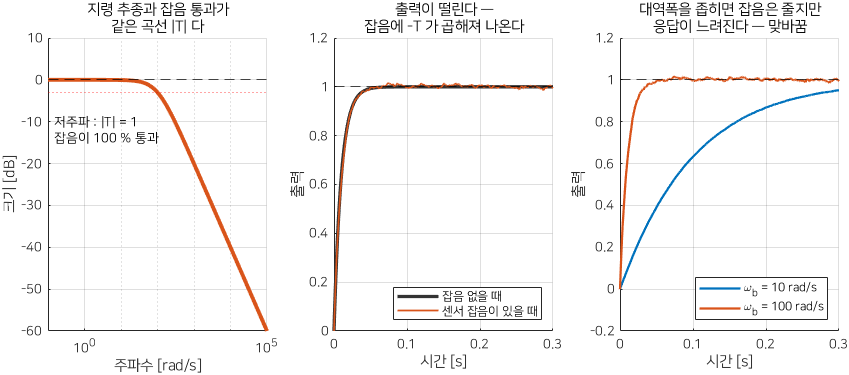

되먹임의 대가 — 잡음은 T 를 타고 들어온다

**그림 파일** `w11a_noise.png` — `make_figures.m` 의 `fig_w11a_noise` · 다시 만들려면 `make_figures('w11a_noise')`

**직접 확인해 보려면** — `W11A_04_disturbance_noise.m` 의 **3절**

그림 해석

오른쪽 그림이 핵심입니다. 잡음을 줄이려고 대역폭을 좁히면 응답이 느려집니다. **빠르게 하면서 잡음도 적게 하는 방법은 없습니다.**

얼마나 남는지 숫자로 셀 수도 있습니다. 샘플 간격 $T_s$ 로 만든 백색잡음은 $0$ 부터 $\pi/T_s$ 까지 **고르게** 퍼져 있고, $-T$ 는 대역폭까지만 통과시킵니다. 그래서 출력 분산은 통과한 띠만큼만 남습니다.


$$\sigma_y^2 = \frac{\sigma_n^2 \, T_s}{2\pi} \int_{-\pi/T_s}^{\pi/T_s} |T(j\omega)|^2 \, d\omega$$


실습 3절이 이 적분을 `trapz` 로 계산해 실측 표준편차와 대조합니다. $T_s = 10^{-4}$, $\sigma_n = 0.02$, 대역폭 $100$ rad/s 에서 식은 $0.001413$, 실측은 $0.001408$ 로 $0.4\,\%$ 차이입니다. **입력의 **$7\,\%$** 만 남은 것**입니다.

- **[주의] 표준편차를 재려면 기록이 충분히 길어야 합니다.** 대역폭이 $100$ rad/s 이면 독립된 표본이 초당 $30$ 개 남짓입니다. $0.5$ 초짜리 기록으로는 표준편차가 $30\,\%$ 넘게 틀어집니다. 그래서 실습은 그림용으로 $0.5$ 초, 숫자 확인용으로 $20$ 초를 따로 씁니다

- 틀어진 값을 보고 "식이 틀렸나" 를 의심하기 쉽지만, **통계량은 표본 수가 모자라면 틀리는 것이 정상**입니다. 적분이나 보간을 고칠 문제가 아닙니다

## 6-1. 오차 예산 — 세 항을 한 식에 모은다

왜 필요한가 — 지금까지 지령, 외란, 잡음을 따로 봤습니다. 실제로는 세 개가 동시에 들어옵니다. 중첩원리(선형시스템)로 더하면 됩니다.

각 전달함수를 모으면 이렇습니다.


$$y = T\, r \;+\; S\, d_o \;+\; P S\, d_i \;-\; T\, n$$


네 항이 각각 무엇인지 왼쪽부터 짚습니다.

- $T\,r$ — **따라가고 싶은 것.** 이 항만 크게 만들고 싶다

- $S\,d_o$ — 출력외란이 남긴 것

- $P S\, d_i$ — 입력외란이 남긴 것

- $-T\,n$ — 센서 잡음이 들어온 것. 부호가 음수다

이것을 **오차 예산**(error budget) 이라고 부릅니다. 네 항이 각각 어느 주파수 띠에서 문제가 되는지 정리합니다.

**네 항 중 셋이 저주파에서 **$|L|$** 을 크게 하라고 하고, 하나가 고주파에서 작게 하라고 합니다.** 요구가 서로 다른 주파수에 있어서 둘 다 만족시킬 수 있습니다. 이것이 루프 성형이 가능한 근본적인 이유입니다.

모터 루프로 세 항의 크기를 한 번 재 봅니다. 저주파 외란 $d_o$ 와 고주파 잡음 $n$ 이 동시에 들어오는 경우입니다.

tb = (0:1e-4:1)';
rng(0);
r_sig = ones(size(tb));                      % 계단 지령
d_sig = 0.3*sin(2*pi*tb);                    % 1 Hz 출력외란
n_sig = 0.02*randn(size(tb));                % 고주파 센서 잡음
y_r = lsim(Tm,  r_sig, tb);
y_d = lsim(Sm,  d_sig, tb);
y_n = lsim(-Tm, n_sig, tb);
table([max(abs(r_sig)); max(abs(d_sig)); max(abs(n_sig))], ...
      [max(abs(y_r)); max(abs(y_d(tb>0.5))); max(abs(y_n(tb>0.5)))], ...
    'RowNames', {'지령_r', '외란_d', '잡음_n'}, ...
    'VariableNames', {'입력_진폭', '출력_기여'})

지령은 1 이 그대로 1 로 나오고 (좋다), 외란 0.3 은 0.019 로 줄고 (좋다), 잡음 0.02 는 0.019 가 거의 그대로 나옵니다 (어쩔 수 없다).

잡음 기여가 줄지 않는 이유 — `randn` 잡음은 모든 주파수에 퍼져 있고, 그중 **저주파 성분은 **$|T| = 1$** 로 100 % 통과**합니다. 센서 잡음을 줄이는 진짜 방법은 제어기가 아니라 **더 좋은 센서**입니다. 제어 설계로 막을 수 있는 것은 고주파 성분뿐입니다.

왜 중요한가 — 11B 주차 종합 설계의 5단계에서 저역통과 필터를 붙이는 이유가 이것입니다. 그리고 그 필터가 위상여유를 깎아서 다시 조정해야 하는 것까지, 전부 이 절의 맞바꿈에서 나옵니다.

## 7. 오늘의 정리

오늘 배운 것을 한 장으로 압축합니다. **이 표만 외워도 됩니다.**

그리고 $S + T = 1$ — 둘을 동시에 작게 만들 수 없다. 그래서 주파수를 나눠서 쓴다.

네 숫자를 읽는 자리를 다시 확인합니다.

서로의 관계 세 개입니다. 전부 어림셈이지만 실무에서 그대로 씁니다.

네 개의 신호가 출력에 어떻게 기여하는가 — 오차 예산입니다.


$$y = T\,r + S\,d_o + P S\,d_i - T\,n$$


그리고 **왜 되먹임인가** 에 대한 답.

마지막으로 **대가**. 되먹임은 센서 잡음을 $-T$ 로 끌어들입니다. 지령 추종과 같은 전달함수이므로 피할 수 없고, 고주파에서 $|L|$ 을 떨어뜨려 막습니다.

## 8. 다음 시간 예고 — 그 모양을 어떻게 만드는가

오늘은 **어떤 모양이 좋은 모양인지** 배웠습니다. 다음 시간(11B)에는 **그 모양을 실제로 만드는 도구**를 배웁니다.

그리고 이 모든 것을 **마우스로 끌어서** 하는 도구를 씁니다. `controlSystemDesigner` 앱입니다. 7주차에 근궤적으로 한 번 만난 그 앱을, 이번에는 보드 선도 쪽에서 씁니다.

다음 시간에 답할 질문들입니다.

- 저주파 이득을 올리면 왜 위상여유가 사라지는가, 그리고 어떻게 되살리는가

- PD 와 Lead 는 둘 다 위상을 올리는데 왜 Lead 를 쓰는가

- 앱에서 동그라미와 x 를 끌면 무엇이 변하고 무엇이 안 변하는가

- 사양 다섯 개를 어떻게 다섯 단계로 나눠 맞추는가

- 공칭 모델로 다 맞춰 놓고 실제 시스템에서 확인하면 무엇이 달라지는가

오늘 배운 표 하나 ($L$, $S$, $T$ 와 세 띠) 를 머리에 넣어 두면 다음 시간은 그 표를 손으로 실현하는 작업이 됩니다.